# Convulotional Neural Network for Star Tracker

% Carica il file .mat
load('data.mat');

%numero di immagini
n=length(data);
% n=90;

% Inizializza array per immagini e coordinate
img_size = size(data(1).img); % le immagini hanno la stessa dimensione
mask_size=size(data(1).mask);



X = zeros([img_size, n], 'like', data(1).img);
Y = zeros([mask_size, n], 'like', data(1).mask);  % Matrice delle coordinate


% Ciclo su tutte le immagini per estrarre i dati
for i = 1:n
    % Immagini pre-elaborate
    X(:, :,:,i) = data(i).img;

    % Coordinate delle stelle (keypoints)
    Y(:, :, i) = data(i).mask;
end



% Mescola gli indici in modo casuale
idx = randperm(n);

% Definisci le proporzioni
train_ratio = 0.7;
val_ratio = 0.2;
test_ratio = 0.1;

% Numero di dati per ciascun insieme
n_train = round(n * train_ratio);
n_val = round(n * val_ratio);
n_test = n - n_train - n_val;  % Il rimanente per il test

% Dati di training
X_train = X(:, :, :, idx(1:n_train));
Y_train = Y(:, :, idx(1:n_train));

% Dati di validazione
X_val = X(:, :, :, idx(n_train+1:n_train+n_val));
Y_val = Y(:, :, idx(n_train+1:n_train+n_val));

% Dati di test
X_test = X(:, :, :, idx(n_train+n_val+1:end));
Y_test = Y(:, :, idx(n_train+n_val+1:end));



 


% Reshape per rendere compatibili i dati di target e quelli di output
Y_train = reshape(Y_train, [128,128,1,n_train]); 
Y_val = reshape(Y_val, [128,128,1,n_val]);
Y_test = reshape(Y_test, [128,128,1,n_test]);
 
%Associazione label personalizzate
Y_train = dlarray(Y_train, 'SSCB');
Y_val = dlarray(Y_val, 'SSCB');
Y_test = dlarray(Y_test, 'SSCB');


% Definizione della rete
layers = [
    imageInputLayer([img_size(1) img_size(2) 3], 'Normalization', 'none')
    
    convolution2dLayer(3, 32, "Padding", "same")
    reluLayer

    maxPooling2dLayer(2, "Stride", 2)    
    batchNormalizationLayer

    convolution2dLayer(3, 64, "Padding", "same")
    reluLayer

    maxPooling2dLayer(2, "Stride", 2)
    batchNormalizationLayer

    convolution2dLayer(3, 128, "Padding", "same")
    reluLayer

    batchNormalizationLayer

    transposedConv2dLayer(3,32,"Stride",2,"Cropping","same")

    transposedConv2dLayer(3,32,"Stride",2,"Cropping","same")

    convolution2dLayer(1,1)
    
        
];

% Opzioni di addestramento
options = trainingOptions('adam', ...
    'InitialLearnRate',3e-4, ...
    'MaxEpochs',50, ...
    'MiniBatchSize',64,...
    'Plots','training-progress',...
    'ValidationData', {X_val, Y_val}, ...
    'ValidationFrequency',10,...
     'L2Regularization',0.005,...
    'InputDataFormats','SSCB',...
    'TargetDataFormats','SSCB');



[trainedNet,info] = trainnet(X_train,Y_train, layers,'mse' ,options);

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:14       0.0003                            34.242
            1        1       00:00:15       0.0003         0.13987                  
           10        1       00:01:06       0.0003         0.02376          0.019248
           20        2       00:02:04       0.0003        0.010497         0.0089971
           30        3       00:03:13       0.0003       0.0066975         0.0065182
           40        4       00:04:20       0.0003       0.0052639         0.0052232
           50        5       00:05:26       0.0003       0.0045926         0.0045645
           60        6       00:06:38       0.0003        0.004203         0.0041903
           70        7       00:07:45       0.0003       0.0039415         0.0039534
           80        8       00:08:53       0.0003       0.003738


info.TrainingHistory

ans = 500×4 table
    Iteration    Epoch    LearnRate      Loss  
    _________    _____    _________    ________

        1          1       0.0003       0.13987
        2          1       0.0003      0.090035
        3          1       0.0003      0.068799
        4          1       0.0003      0.056012
        5          1       0.0003      0.046565
        6          1       0.0003      0.038679
        7          1       0.0003      0.032499
        8          1       0.0003      0.028856
        9          1       0.0003       0.02568
       10          1       0.0003       0.02376
       11          2       0.0003      0.020913
       12          2       0.0003      0.018633
       13          2       0.0003      0.016727
       14          2       0.0003      0.014708
       15          2       0.0003      0.013915
       16          2       0.

info.ValidationHistory

ans = 51×2 table
    Iteration      Loss   
    _________    _________

         0          34.242
        10        0.019248
        20       0.0089971
        30       0.0065182
        40       0.0052232
        50       0.0045645
        60       0.0041903
        70       0.0039534
        80       0.0038005
        90       0.0036586
       100       0.0035448
       110       0.0034384
       120        0.003351
       130       0.0032763
       140        0.003207
       150       0.0031333




% Predizioni
Y_pred = minibatchpredict(trainedNet, X_test);
Y_pred=double(Y_pred);
% Errore quadratico medio (MSE) per il set di validazione
mse_val = mean((Y_test - Y_pred).^2, 'all');

% Errore quadratico medio radice (RMSE)
rmse_val = sqrt(mse_val);

% Risultati
fprintf('Validation MSE: %.4f\n', mse_val);

Validation MSE: 0.0019


fprintf('Validation RMSE: %.4f\n', rmse_val);

Validation RMSE: 0.0431


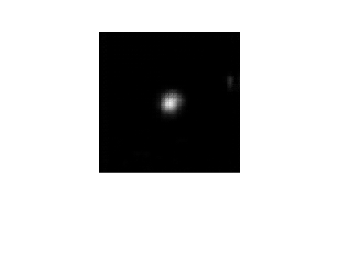

figure
imshow(Y_pred(:,:,:,9))

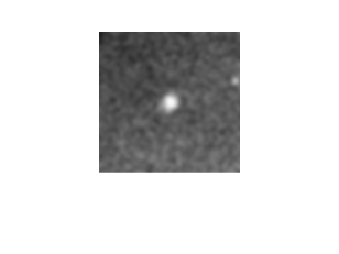

imshow(X_test(:,:,:,9))